Live script to extract features of tdms files

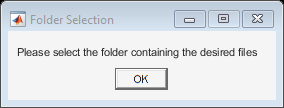

fileStruct = struct with fields:
    folderPath: 'G:\Semester Arbeit\Programming\data\converted_data\damaged\Gruebchen_Ritzel_Rad_leicht'
    folderName: 'Gruebchen_Ritzel_Rad_leicht'
         files: {1×18 cell}


Gruebchen_Ritzel_Rad_leicht


fileStruct = selectFiles();

Give the following information

If the folder name is not accurate enough there is the possibility to add your own label

label = askForLabel(fileStruct.folderName);

sampling_frequency = 100000; %in Hz
decimateFactor = 10;
channel_selection = [1,2];
num_teeth_gear = 22;
sideband_length = 100;
segment_length = 1000; 
overlap = 500;

files = fileStruct.files;
folderPath = fileStruct.folderPath;
% Initialize a cell array to store the features for each file
allFeatures = cell(1, length(files));

parfor i = 1:length(files)
    % Extract torque and speed data
    [torque, speed] = extractTorqueAndSpeed(files{i});
    gearMeshFreq = calculate_gearMeshFreq(num_teeth_gear, speed);
    %disp(gearMeshFreq)
    
    % Read the TDMS file and get signal data
    [tdmsTable, ch_selection] = readTdmsFile(folderPath, files{i}, channel_selection);
    signal_columns = tdmsTable{:,:};  % Convert the tdmsTable to matrix for easier indexing
    
    % Decimate the signal
    decimated_signal_columns = decimateSignal(signal_columns, decimateFactor);
    
    % Update the sampling frequency after decimation
    new_sampleFrequency = sampling_frequency / decimateFactor;
    
    % Calculate the number of segments
    num_segments = floor((height(decimated_signal_columns) - overlap) / (segment_length - overlap));
    
    % Initialize a struct or cell array to store the features for each segment
    features = [];  % Or use `cell(num_segments, 1)` if needed
    
    % Loop through each segment and extract features
    for seg = 1:num_segments
        % Calculate the start and end indices for the current segment
        start_idx = (seg-1) * (segment_length - overlap) + 1;
        end_idx = start_idx + segment_length - 1;
        
        % Extract the segment from the decimated signal
        segment = decimated_signal_columns(start_idx:end_idx, :);
        
        % Extract frequency features for the current segment using the new sampling frequency
        frequencyFeatures = extractBandwidthFrequencyFeatures(segment, new_sampleFrequency, gearMeshFreq, sideband_length, channel_selection);
        
        % Create a struct for this segment with torque, speed, and label first
        combinedFeatures = struct();
        combinedFeatures.torque = torque;
        combinedFeatures.speed = speed;
        combinedFeatures.label = label;  % Add the label variable
        
        % Merge the frequency features into the combinedFeatures struct
        combinedFeatures = catstruct(combinedFeatures, frequencyFeatures);
        
        % Append the combined features to the features array
        features = [features; combinedFeatures];  % Or use a preallocated array
    end
    
    % Store the features for the current file in the cell array
    allFeatures{i} = features;
end

% Optionally, combine all the features into one big array or table
combinedFeatures = vertcat(allFeatures{:});  % Concatenate vertically if necessary